# Example script showing a generalization of the subspace method for the case when

## the two dichromats do not share exactly a cone fundamental.

The script adds deformation and noise to the cone fundamentals

TG 2023-04-01: This script is stochastic. Run this several times to see the difference. Most of the time the reconstruction is very satisfactory. In other cases it is terrible for some cones. I need to think a bit more where this comes from. Probably because randn gives very big numbers sometimes.

Created By Thomas Goossens  2023

close all;
nbWavelengths=100;
wl_start_nm = 400;


% Helper function to normalize data
n=@(A)A/max(abs(A(:))); % normalize

## Generate LMS cones for three different individuals

We generate three individuals with different LMS cones.

coneParams = DefaultConeParams('cie_asano');
% wl start , stepsize , number of steps
S = [wl_start_nm 1 301];
lambda=SToWls(S);

% Individual 1
coneParams.indDiffParams.dmac=0;
coneParams.indDiffParams.dlens=0;
LMS(:,:,1) = ComputeObserverFundamentals(coneParams,S)';

% Individual 2
coneParams.indDiffParams.dmac=50;
 coneParams.indDiffParams.dlens=50;
LMS(:,:,2) = ComputeObserverFundamentals(coneParams,S)';

% Individual 3
coneParams.indDiffParams.dmac=100;
coneParams.indDiffParams.dlens=100; 
LMS(:,:,3)= ComputeObserverFundamentals(coneParams,S)';

%% Organize L M and S cones in separate matrices.
for i=1:3
    l(:,i)=LMS(:,1,i);
    m(:,i)=LMS(:,2,i);
    s(:,i)=LMS(:,3,i);
end

%% plot the three L, M and S cones
figure;
hold on

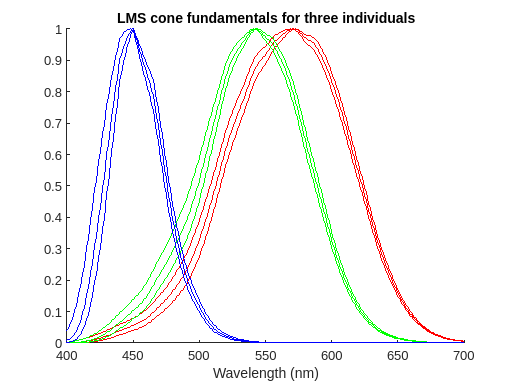

plot(lambda,l,'r')
plot(lambda,m,'g')
plot(lambda,s,'b')
title('LMS cone fundamentals for three individuals')
xlabel('Wavelength (nm)')   
exportgraphics(gcf,'fig/cones.pdf')

## Construct the color matching functions for three types of dichromats (leaving out one of the cones)

For each type we leave out one cone fundamental and apply a multiplication with a random 2x2 matrix (we can choose a more relistic one later)

%Protanope (Leave out L)
Cp=rand(2); 
P=[m(:,1) s(:,1)]*Cp;
% Deuteranope   (leave out M)
Cd=rand(2);
D=[l(:,2) s(:,2)]*Cd;
% Tritanope (leave out S)
Ct=rand(2);
T=[l(:,3) m(:,3)]*Ct;

noiselevel =0* 3e-3

noiselevel = 0

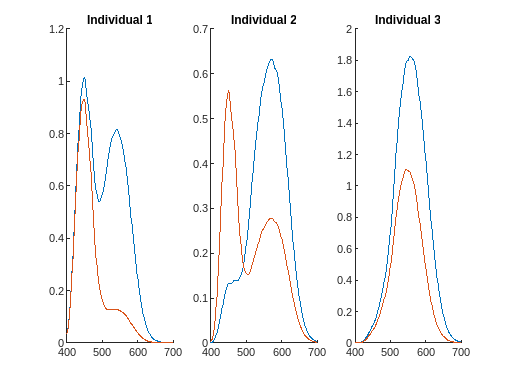

P = P + noiselevel*randn(size(P));
D = D + noiselevel*randn(size(D));
T = T + noiselevel*randn(size(T));
figure;
title('Colormatching functions for each dichromat')
subplot(131)
hold on;plot(lambda,P)
title('Individual 1')
subplot(132)
title('Individual 2')
hold on;plot(lambda,D)
subplot(133)
title('Individual 3')
hold on;plot(lambda,T)

## The null space is null: there is no intersection between the subspaces

This is because the individuals do not actually share a cone fundamental exactly. We can use the SVD to approximate it.

nullspace=null([P D]) % is empty


nullspace =

  4×0 empty double matrix



## Estimate L cone fundamentals

[U,S,V] = svd([D T]);
V4=V(:,4)

V4 =    -0.7489
    0.1473
    0.4834
   -0.4286


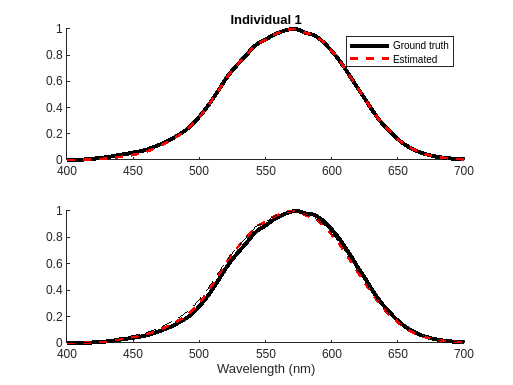

% We can formulate an estimate in both subspaces(column spaces) 
L_estimate_1 = D*V4(1:2); %individual 1
L_estimate_2 = T*V4(3:4); %individual 2

figure; hold on;
subplot(211); hold on
plot(lambda,l(:,2),'k-','linewidth',3)
plot(lambda,abs(L_estimate_1)/max(abs(L_estimate_1)),'r--','linewidth',2)
legend('Ground truth','Estimated')
title('Individual 1')

subplot(212); hold on
plot(lambda,l(:,3),'k-','linewidth',3)
plot(lambda,abs(L_estimate_2)/max(abs(L_estimate_2)),'r--','linewidth',2)
plot(lambda,l(:,2),'k--')
xlabel('Wavelength (nm)')

## Estimate M cone fundamentals

[U,S,V] = svd([P T]);
V4=V(:,4)

V4 =     0.5357
   -0.5639
    0.1640
   -0.6067


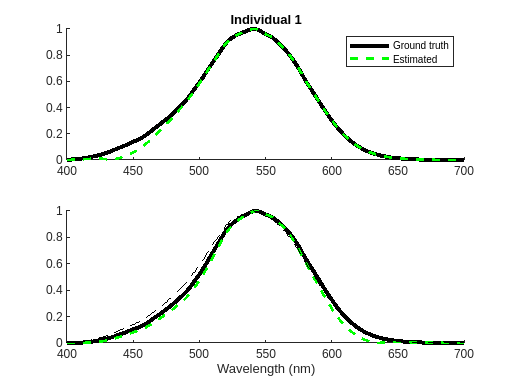

% We can formulate an estimate in both subspaces(column spaces) 
M_estimate_1 = P*V4(1:2); %individual 1
M_estimate_2 = T*V4(3:4); %individual 2

figure; hold on;
subplot(211); hold on
plot(lambda,m(:,1),'k-','linewidth',3)
plot(lambda,abs(M_estimate_1)/max(abs(M_estimate_1)),'g--','linewidth',2)
legend('Ground truth','Estimated')
title('Individual 1')

subplot(212); hold on
plot(lambda,m(:,2),'k-','linewidth',3)
plot(lambda,abs(M_estimate_2)/max(abs(M_estimate_2)),'g--','linewidth',2)
plot(lambda,m(:,1),'k--')
xlabel('Wavelength (nm)')

## Estimate S cone fundamentals

[U,S,V] = svd([P D]);
V4=V(:,4)

V4 =     0.0708
   -0.4880
   -0.3507
    0.7961


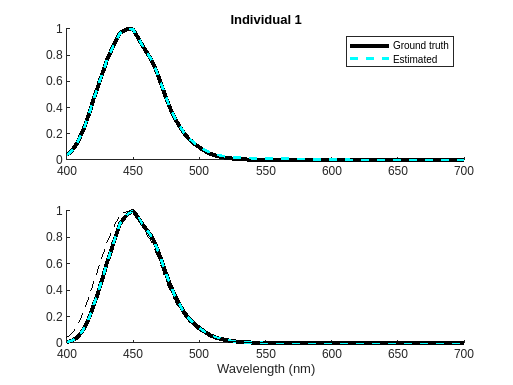

% We can formulate an estimate in both subspaces(column spaces) 
S_estimate_1 = P*V4(1:2); %individual 1
S_estimate_2 = D*V4(3:4); %individual 2

figure; hold on;
subplot(211); hold on
plot(lambda,s(:,1),'k-','linewidth',3)
plot(lambda,abs(S_estimate_1)/max(abs(S_estimate_1)),'c--','linewidth',2)
legend('Ground truth','Estimated')
title('Individual 1')

subplot(212); hold on
plot(lambda,s(:,2),'k-','linewidth',3)
plot(lambda,abs(S_estimate_2)/max(abs(S_estimate_2)),'c--','linewidth',2)
plot(lambda,s(:,1),'k--')
xlabel('Wavelength (nm)')   

## One plot

[U,S,V] = svd([P D]);
V4=V(:,4)

V4 =     0.0708
   -0.4880
   -0.3507
    0.7961


% We can formulate an estimate in both subspaces(column spaces) 
S_estimate_1 = P*V4(1:2); %individual 1
S_estimate_2 = D*V4(3:4); %individual 2

figure; hold on;
S

S =    12.4829         0         0         0
         0    4.9004         0         0
         0         0    1.7424         0
         0         0         0    0.3338
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


href=plot(lambda,l(:,2),'k:','linewidth',2)

href =   Line with properties:

              Color: [0 0 0]
          LineStyle: ':'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [400 401 402 403 404 405 406 407 408 409 410 411 412 413 414 415 416 417 418 419 420 421 422 423 424 425 426 427 428 429 430 431 432 433 434 435 436 437 438 439 440 441 442 443 444 445 446 447 448 449 450 451 452 453 454 455 456 … ]
              YData: [3.4797e-04 4.3670e-04 5.4657e-04 6.8306e-04 8.5343e-04 0.0011 0.0013 0.0016 0.0019 0.0023 0.0028 0.0032 0.0037 0.0043 0.0050 0.0058 0.0064 0.0072 0.0081 0.0091 0.0103 0.0111 0.0121 0.0131 0.0143 0.0155 0.0167 0.0179 0.0193 … ]

  Show all properties

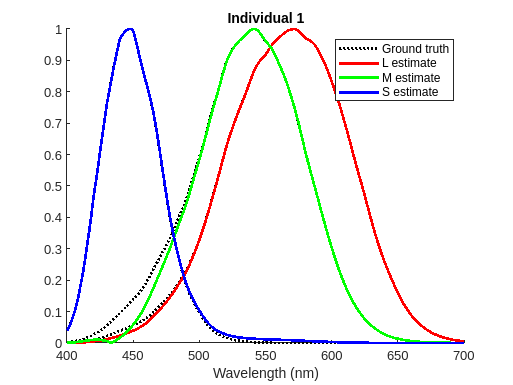

plot(lambda,m(:,1),'k:','linewidth',2);
plot(lambda,s(:,1),'k:','linewidth',2);
hL=plot(lambda,abs(L_estimate_1)/max(abs(L_estimate_1)),'r-','linewidth',2);
hM=plot(lambda,abs(M_estimate_1)/max(abs(M_estimate_1)),'g-','linewidth',2);
hS=plot(lambda,abs(S_estimate_1)/max(abs(S_estimate_1)),'b-','linewidth',2);

legh=legend([href, hL hM hS],'Ground truth','L estimate','M estimate','S estimate');
title('Individual 1')
xlabel('Wavelength (nm)')

exportgraphics(gcf,'fig/individual1.pdf')


figure; hold on;

href=plot(lambda,l(:,3),'k:','linewidth',2);
plot(lambda,m(:,2),'k:','linewidth',2);
plot(lambda,s(:,2),'k:','linewidth',2);
hL=plot(lambda,abs(L_estimate_2)/max(abs(L_estimate_2)),'r-','linewidth',2);
hM=plot(lambda,abs(M_estimate_2)/max(abs(M_estimate_2)),'g-','linewidth',2);
hS=plot(lambda,abs(S_estimate_2)/max(abs(S_estimate_2)),'b-','linewidth',2);

title('Individual 2')
xlabel('Wavelength (nm)')
legh=legend([href, hL hM hS],'Ground truth','L estimate','M estimate','S estimate')

legh =   Legend (Ground truth, L estimate, M estimate, S estimate) with properties:

         String: {'Ground truth'  'L estimate'  'M estimate'  'S estimate'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.6756 0.7544 0.2107 0.1464]
          Units: 'normalized'

  Show all properties


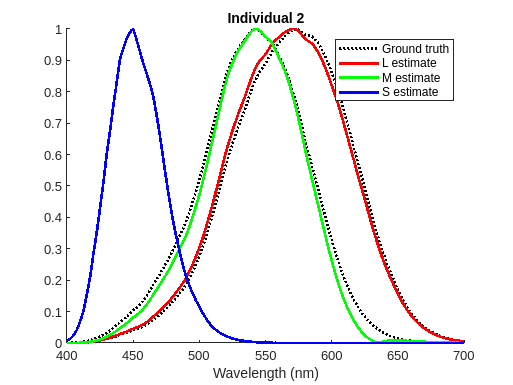

exportgraphics(gcf,'fig/individual2.pdf')

## Just try a brute force solver

% Structureof the unknowns
% 
% C=[0 0  x x   x x 
%    x x  0 0   x x 
%    x x  x x   0 0  ]
%
% known   = unknownLMS*unknownC
% [P D T] = [l m s]*C
% [P D T] = [x_1 X_n+1 x_2*n+1
%            x_2 ..           ]*C
%

% Assume shared cones identical
%Protanope (Leave out L)
Cp=rand(2); 
P=[m(:,1) s(:,1)]*Cp;
% Deuteranope   (leave out M)
Cd=rand(2);
D=[l(:,1) s(:,1)]*Cd;
% Tritanope (leave out S)
Ct=rand(2);
T=[l(:,1) m(:,1)]*Ct;


% LMS has 3*N unknowns
nLMS = numel(LMS(:,:,1))

nLMS = 903

nbx = nLMS+4*3; % total number of unknowns
x = abs(randn(1,nbx));
% Initalizing the problem well makes it converge
x(1:3*N) = reshape(LMS(:,:,1),[3*N 1])

x =     0.0025    0.0030    0.0034    0.0040    0.0046    0.0053    0.0060    0.0068    0.0078    0.0088    0.0100    0.0110    0.0121    0.0133    0.0146    0.0160    0.0172    0.0186    0.0200    0.0216    0.0234    0.0247    0.0261    0.0276    0.0292    0.0309    0.0325    0.0341    0.0358    0.0377    0.0398    0.0415    0.0433    0.0453    0.0473    0.0494    0.0513    0.0532    0.0552    0.0573    0.0595    0.0611    0.0629    0.0647    0.0667    0.0687    0.0707    0.0727    0.0749    0.0772



N = size(LMS,1)

N = 301

LMS_unknown = @(x) [x(1:N)' x(N+1:2*N)' x(2*N+1:3*N)']

LMS_unknown = function_handle with value:
    @(x)[x(1:N)',x(N+1:2*N)',x(2*N+1:3*N)']


%xc = x(3*N+1:end);
%C_unknown = @(xc) [0 0     0      xc(5) 0 xc(7)   xc(9) xc(11) 0
 %           0 xc(1) xc(3)  0     0   0     xc(10) xc(12) 0
  %         0 xc(2) xc(4)  xc(6) 0 xc(8)   0 0 0  ]
C_unknown = @(xc) [ 0     0      xc(5)  xc(7)   xc(9) xc(11)
                   xc(1) xc(3)  0       0     xc(10) xc(12) 
                   xc(2) xc(4)  xc(6) xc(8)   0 0  ]

C_unknown = function_handle with value:
    @(xc)[0,0,xc(5),xc(7),xc(9),xc(11);xc(1),xc(3),0,0,xc(10),xc(12);xc(2),xc(4),xc(6),xc(8),0,0]



PDT = [P D T]

PDT =     0.0168    0.0388    0.0256    0.0118    0.0017    0.0028
    0.0198    0.0457    0.0301    0.0138    0.0020    0.0033
    0.0233    0.0539    0.0355    0.0163    0.0023    0.0039
    0.0274    0.0634    0.0417    0.0191    0.0027    0.0045
    0.0322    0.0745    0.0491    0.0224    0.0031    0.0052
    0.0378    0.0876    0.0576    0.0263    0.0036    0.0060
    0.0434    0.1006    0.0662    0.0302    0.0041    0.0069
    0.0499    0.1155    0.0759    0.0346    0.0046    0.0078
    0.0572    0.1325    0.0871    0.0397    0.0053    0.0089
    0.0656    0.1520    0.0998    0.0454    0.0060    0.0101


F = @(x) norm(PDT-LMS_unknown(x)*C_unknown(x(3*N+1:end)))

F = function_handle with value:
    @(x)norm(PDT-LMS_unknown(x)*C_unknown(x(3*N+1:end)))



% Force LMS functions to be nonnegative
%Aineq = diag([ones(1,3*N) ones(1,nbx-3*N)]);
%bineq = ones(nbx,1);;

xsol = fmincon(F,x)


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.



xsol =     0.0028    0.0032    0.0038    0.0044    0.0051    0.0059    0.0067    0.0076    0.0086    0.0098    0.0111    0.0123    0.0135    0.0149    0.0164    0.0180    0.0194    0.0209    0.0226    0.0244    0.0264    0.0279    0.0295    0.0312    0.0330    0.0350    0.0367    0.0385    0.0405    0.0426    0.0448    0.0467    0.0487    0.0508    0.0530    0.0552    0.0572    0.0593    0.0614    0.0636    0.0659    0.0676    0.0694    0.0713    0.0732    0.0753    0.0773    0.0793    0.0815    0.0838



maxnorm = @(A) A*diag(max(A).^-1)

maxnorm = function_handle with value:
    @(A)A*diag(max(A).^-1)


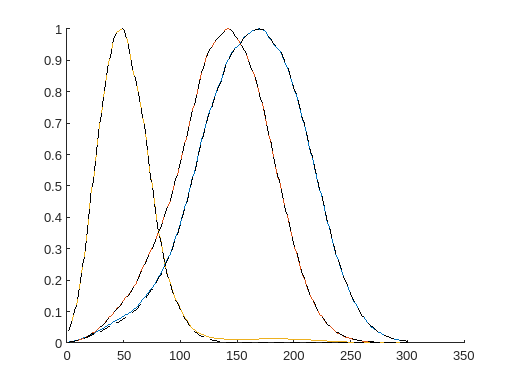

figure; hold on
plot(maxnorm(LMS_unknown(xsol)))
plot(LMS(:,:,1),'k--')